# CSSC System Identification Workshop

## Physics-based Modeling of Active Suspension System 

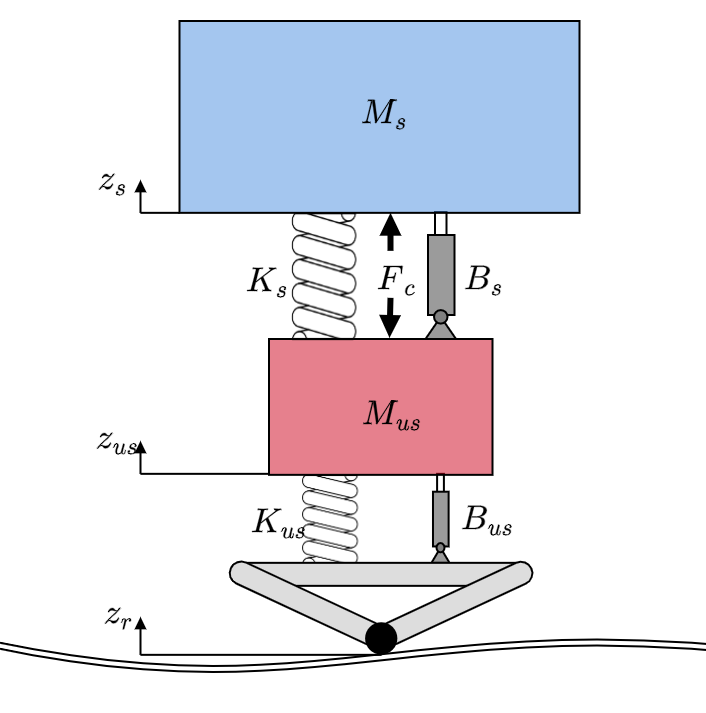


$$\left\lbrack \begin{array}{c}
{\dot{z} }_{us} -{\dot{z} }_r \\
{\ddot{z} }_{us} \\
{\dot{z} }_s -{\dot{z} }_{us} \\
{\ddot{z} }_s 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{K_{us} }{M_{us} } & -\frac{B_s +B_{us} }{M_{us} } & \frac{K_s }{M_{us} } & \frac{B_s }{M_{us} }\\
0 & -1 & 0 & 1\\
0 & \frac{B_s }{M_s } & -\frac{K_s }{M_s } & -\frac{B_s }{M_s }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_{us} -z_r \\
{\dot{z} }_{us} \\
z_s -z_{us} \\
{\dot{z} }_s 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
-\frac{1}{M_{us} }\\
0\\
\frac{1}{M_s }
\end{array}\right\rbrack u+\left\lbrack \begin{array}{cc}
-1 & 0\\
\frac{B_{us} }{M_{us} } & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{z} }_r \\
z_r 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
z_{us} \\
z_s \\
{\ddot{z} }_s 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
1 & 0 & 1 & 0\\
0 & \frac{B_s }{M_s } & -\frac{K_s }{M_s } & -\frac{B_s }{M_s }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_{us} -z_r \\
{\dot{z} }_{us} \\
z_s -z_{us} \\
{\dot{z} }_s 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
\frac{1}{M_s }
\end{array}\right\rbrack u+\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{z} }_r \\
z_r 
\end{array}\right\rbrack$$


The goal of this section is to compare the active suspension system model that we have derived using physics to the actual system. Here we come across our first hurdle of using a physics based model, figuring out all the various parameter values. For this example, let us assume that we have obtained the required parameters from the system manufacturer. Let us check how this model compares to the actual experimental system.

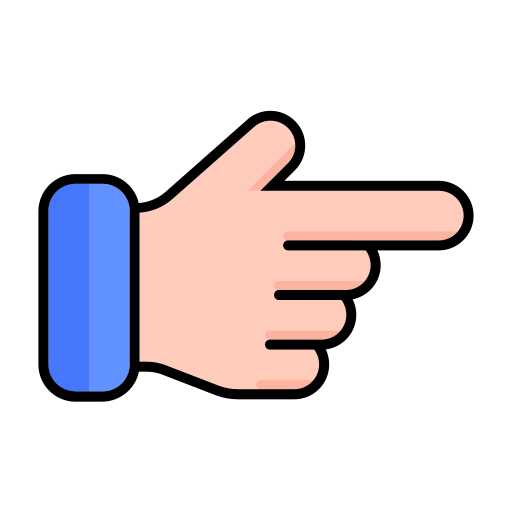 **Steps to do**

- Turn on the experimental system by first turning on the amplifier and then re-calibrate the plate by moving it to the center position and pushing the re-calibration switch, as depicted here, (*Please call for an instructor if help is needed with this step*).

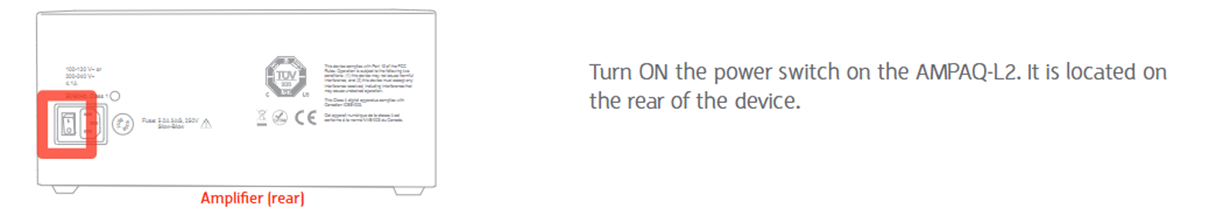            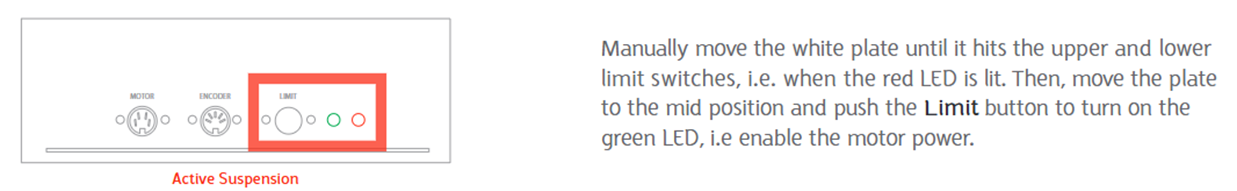

- Click on **Run** to launch the Simulink file for running the experimental system.

- Build the target code in Simulink by clicking on **QUARC** in the toolbar and then **Build** before running the experiment for few seconds to collect experimental data.

  

clear
% System dimensions
nx = 4; % Number of states
nu = 1; % Number of inputs (controllable)
nd = 2; % Number of disturbances
ny = 3; % Number of outputs

% Model parameters
Ks = 900;    % Suspension Stiffness (N/m) 
Kus = 0; %1250;  % Tire stiffness (N/m)
Ms = 2.45;   % Sprung Mass (kg) 
Mus = 1;     % Unsprung Mass (kg)
Bs = 7.5;    % Suspension Inherent Damping coefficient (sec/m)
Bus = 0; %5;     % Tire Inherent Damping coefficient (sec/m)

% Model Definition
Ac = [0 1 0 0
      -(Kus/Mus) -(Bs +Bus)/Mus (Ks/Mus) (Bs/Mus)
      0 -1 0 1
      0 (Bs/Ms) -(Ks/Ms) -(Bs/Ms)];   % State Matrix
Bc = [0; -(1/Mus); 0; (1/Ms)];        % Input Matrix
Vc = [-1 0
      (Bus/Mus) 0
      0 0
      0 0];                           % Disturbance
C = [1 0 0 0
     1 0 1 0
     0 (Bs/Ms) -(Ks/Ms) -(Bs/Ms)];    % Output
D = [0;0;(1/Ms)];                     % Feed-through
W = [0 1
     0 1
     0 0];                            % Output Disturbance

     
addpath('Support\') 
open_system("Support/Workshop_as_sim_part1.mdl")
     

#### Comparing the Physics-based Model and Experimental System

Now let us compare the experimental data against the simulation of the Physics-based model of the active suspension system. 

 **Steps to do**

- Click on **Run** to create the comparison plot of the experimental and model simulation outputs.

- Comment on the model accuracy when compared to the experimental data.

  

% Plot

t = z_s.time;
z_s_exp = z_s.signals(1).values;
ddz_s_exp = ddot_zs.signals(1).values;
z_s_linSys = z_s.signals(2).values;
ddz_s_linSys = ddot_zs.signals(2).values;


figure

subplot(2,1,1)
hold on
plot(t,z_s_exp,'r','LineWidth',1.5)
plot(t,z_s_linSys,'b','LineWidth',1.5)
xlabel('Time (s)',"Interpreter","latex")
ylabel('$z_s$ (m)',"Interpreter","latex")
legend(["Experimental System" "Linear System"])
xlim([0,10])
grid on
hold off

subplot(2,1,2)
hold on
plot(t,ddz_s_exp,'r','LineWidth',1.5)
plot(t,ddz_s_linSys,'b','LineWidth',1.5)
xlabel('Time (s)',"Interpreter","latex")
ylabel('$\ddot{z}_s (m/s^2)$',"Interpreter","latex")
xlim([0,10])
grid on
hold off

## Frequency Response Based System ID

In this section, instead of using a Physics-based model, we will use data from experimental system to directly estimate the model, or in other words *Identify the System*. To do so, we will be using the frequency response of the system to estimate its damping ratio $\zeta 
$ and the natural frequency $\omega $, which then can directly used in the $2^{nd}$ order transfer function estimate of the model,

$G( s) =\frac{\omega ^{2}}{s^{2} +2\zeta \omega s+\omega ^{2}}$.

 **Steps to do**

- Select a input type from the available list of inputs that you want to use for perturbing the active suspension system, and then click on **Run** to generate the signal.

- Build the target code in Simulink by clicking on **QUARC** in the toolbar and then **Build** before running the experiment to collect system response data.

  

Reset;
clear

input_type = 5; % Select Input Signal

u_sim = sysID_setup(input_type,1);


Now that we have collected system response data from the active suspension experimental system, lets try to use it to estimate the transfer function of the system.

 **Steps to do**

- Click on **Run** to perform transfer function identification 

- Comment on the estimated model that you obtained.

  


dt = 0.01;
t = z_s.time;
output1 = z_s.signals.values;
output2 = ddot_zs.signals.values;
input = u.signals.values;

sysID_est(output1,input,t(end));

## Mitigating Signal Noise and Time Delays

Let us now try to make the identification process more realistic, where we will introduce process noise, sensor noise, and input delays to the data we are gathering and then try to estimate the system model.

 **Steps to do**

- Select a input type from the available list of inputs that you want to use for perturbing the active suspension system.

- Choose the different noise, anomalies, and delay that you wish to add to the measured signals by clicking on the check boxes.

- Click on **Run** to generate the signal.

  

Reset;
clear

input_type = 5; % Select Input Signal

u_sim = sysID_setup(input_type,2);

#### Process Noise

use_actuator_pnoise =  true; % Turns on/off actuator process noise


actuator_tf_num = [1]; 
actuator_tf_den = [2*pi 1];
actuator_pnoise_pow = 10;


#### Measurement Noise

% Road measurement
use_roadpos_noise =     true; % Turn on/off road measurement noise
use_roadpos_anomalies = true; % Turn on/off road measurement anomalies

roadpos_noise_pow = 1e-7;
anom_set_size = 100;

% Tire measurement
use_tire_mnoise =       true; % Turn on/off tire measurement noise

tire_mnoise_pow = 1e-7;

% Vehicle body measurement
use_vb_mnoise =         true; % Turn on/off vehicle body measurement noise

vb_mnoise_pow = 1e-7;


#### Input Delay

use_input_delay =       true; %Turn on/off Input Delay

input_delay_length = 100;


#### Estimate Model from Noisy Data

 **Steps to do**

- Click on **Run** to perform transfer function identification 

- Comment on the estimated model that you obtained.

  


dt = 0.01;
t = z_s.time;
output1 = z_s.signals.values;
output2 = ddot_zs.signals.values;
input = u.signals.values;

sysID_est(output1,input,t(end));

## Discovering Nonlinear System Dynamics

Finally, let us have a brief introduction to nonlinear system identification. Consider this general nonlinear dynamic system,


$$\dot{x}( t) \ =\ f( x( t)), $$
                                            
$$(1)$$


where the goal of this exercise is to identify the underlying nonlinear dynamics $f( x( t))$, with the knowledge of states $x( t)$ and state derivatives $\dot{x}( t)$ only. The nonlinear system identification method used here is a simplification based on the work on [Sparse Identification](https://www.pnas.org/doi/full/10.1073/pnas.1517384113) of nonlinear dynamical systems. We will start by first understanding the underlying algorithm required to learn the nonlinear dynamics using a simple Lorenz system and then implement the algorithm to identity the quarter car system model.

#### Lorenz System

The [Lorenz system](https://en.wikipedia.org/wiki/Lorenz_system) is a set of three dimensional ordinary differential equation, first developed by the meteorologist [Edward Lorenz](https://en.wikipedia.org/wiki/Edward_Norton_Lorenz) while studying atmospheric convection. It is a classic example of a system that can exhibit [chaotic](https://en.wikipedia.org/wiki/Chaos_theory) behavior, meaning its output can be highly sensitive to small changes in its starting conditions. The behavior of these three variables is governed by the following equations:

 
$$ \begin{array}{c}
\dot{x} =\sigma ( y-x) ,\\
\dot{y} =x( \rho -z) -y,\\
\dot{z} =xy-\beta z,
\end{array}$$
                                            
$$(2)
$$


where the constants *σ*, *ρ*, and *β* are parameters representing physical properties of the system: *σ* is the [Prandtl number](https://en.wikipedia.org/wiki/Prandtl_number), *ρ* is the [Rayleigh number](https://en.wikipedia.org/wiki/Rayleigh_number), and *β* relates to the physical dimensions of the fluid layer itself. 

We will be using the Lorenz system to motivate the idea of Sparse Identification by exactly identifying the nonlinear dynamics of this system shown in equations $(2)
$ by just using simulated states $[x( t), \ y(t), \ z(t)]^\top$ and state derivatives $[\dot{x}( t), \ \dot{y}( t), \ \dot{z}( t)]^\top$. Let us start by first simulating the Lorenz system with parameters $\rho=28$, $\sigma=10$, and $\beta=\frac{8}{3}$.

 **Steps to do**

- Click on **Run** to simulate the Lorenz system model and plot system response.

  

clear
close all

out = sim("Support\Lorenz_SysID_example.slx");

x = out.x.Data(:,1);
y = out.x.Data(:,2);
z = out.x.Data(:,3);

xdot = out.xdot.Data(:,1);
ydot = out.xdot.Data(:,2);
zdot = out.xdot.Data(:,3);

t = out.tout;


% Plot
figure;
cmap = colormap;
c = round(1+(size(cmap,1)-1)*(t - min(t))/(max(t)-min(t)));
hold on
for i = 1:50:(length(x)-50)
    line(x(i:i+50),y(i:i+50),z(i:i+50),'color',cmap(c(i),:))
end
view(30,20)
xlabel('x','Interpreter','latex')
ylabel('y','Interpreter','latex')
zlabel('z','Interpreter','latex')
title('Lorenz Attractor')
grid on
hold off

#### Sparse Identification of Nonlinear Dynamic Systems

The Sparse Identification algorithm is based on the key observation that many system of interest in nature are inherently sparse in the representation of the function $f( x( t))$, where only few nonlinear terms are needed to describe the complete dynamics of the system. So the knowledge of only few of these nonlinear relations is required to completely identify such system dynamics.

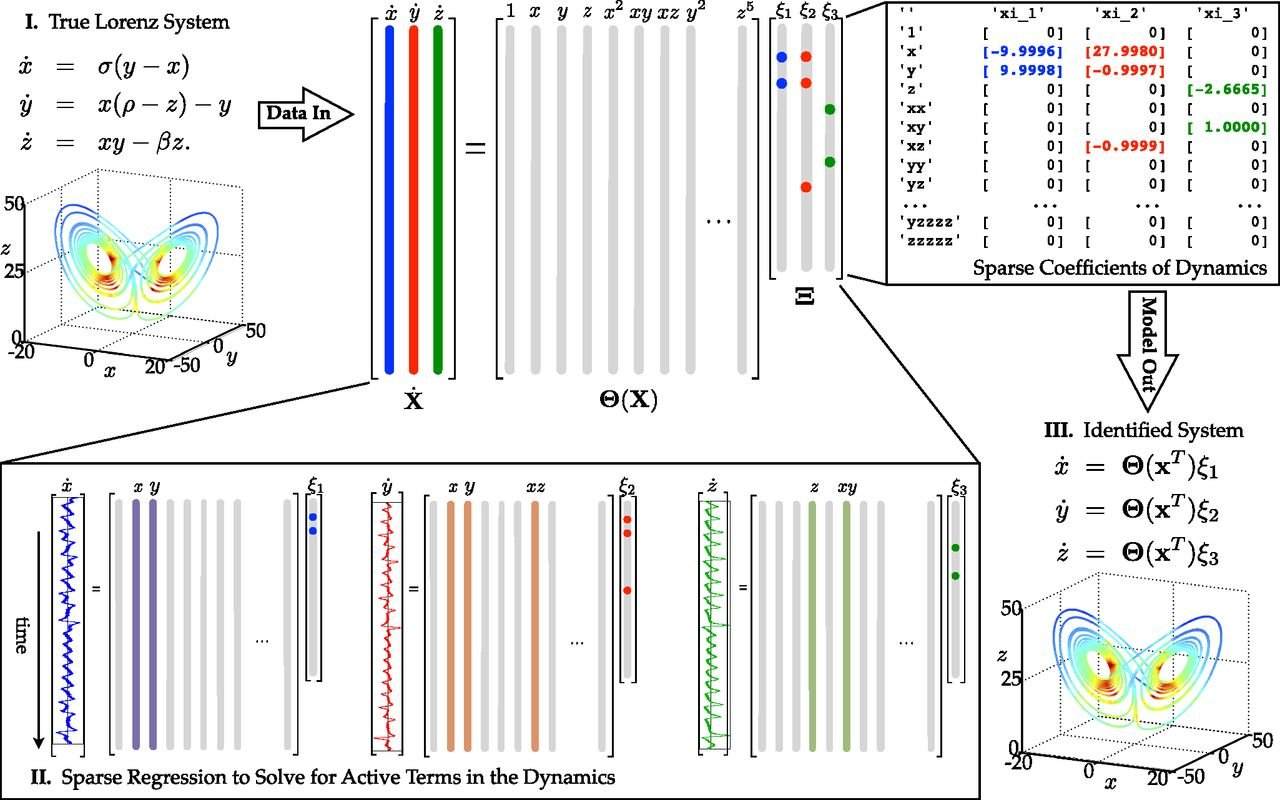

Fig 1. Schematic of the Sparse Identification algorithm, demonstrated on the Lorenz system.

Fig.1 gives a high level idea of how sparse identification algorithm works. The basic idea is that we collect data from the states $[x( t), \ y(t), \ z(t)]^\top$ and state derivatives $[\dot{x}( t), \ \dot{y}( t), \ \dot{z}( t)]^\top$from the sampled data gathered from the simulated system and rewrite the model dynamics as,


$$\mathbf{\dot{X} =\theta ( X) \Xi },
$$
                                            
$$(3)
$$


where $\mathbf{\theta ( X)}$ is a library of candidate nonlinear functions of $\mathbf{X},$

$\mathbf{\theta ( X)} =$$\left\lbrack \begin{array}{cccccccccc}
| & | & | & | & | & | & | & | & | & |\\
1 & x & y & z & x^2  & y^2  & z^2  & \textrm{xy} & \textrm{yz} & \cdots \\
| & | & | & | & | & | & | & | & | & |
\end{array}\right\rbrack$,                                            $(4)
$

and $\mathbf{\Xi }

$ is a vector of sparse coefficients $\left\lbrack \begin{array}{ccc}
\xi_1  & \xi_2  & \xi_3 
\end{array}\right\rbrack$. 

Since we already know what $\mathbf{\dot{X}}$ and $\mathbf{X}$ are from data collected from the simulation, we can solve for the sparse coefficients matrix $\mathbf{\Xi }

$ in equation $(3)
$ to find all the active terms in the  library of candidate nonlinear functions $\mathbf{\theta ( X)}$, allowing us to identify what the governing equations of the nonlinear system is from data. To do so, we will be using least squares regression technique, where we will try to minimize the squared distance between the data and the solution of equation $(3)
$, as depicted in Fig.2. 

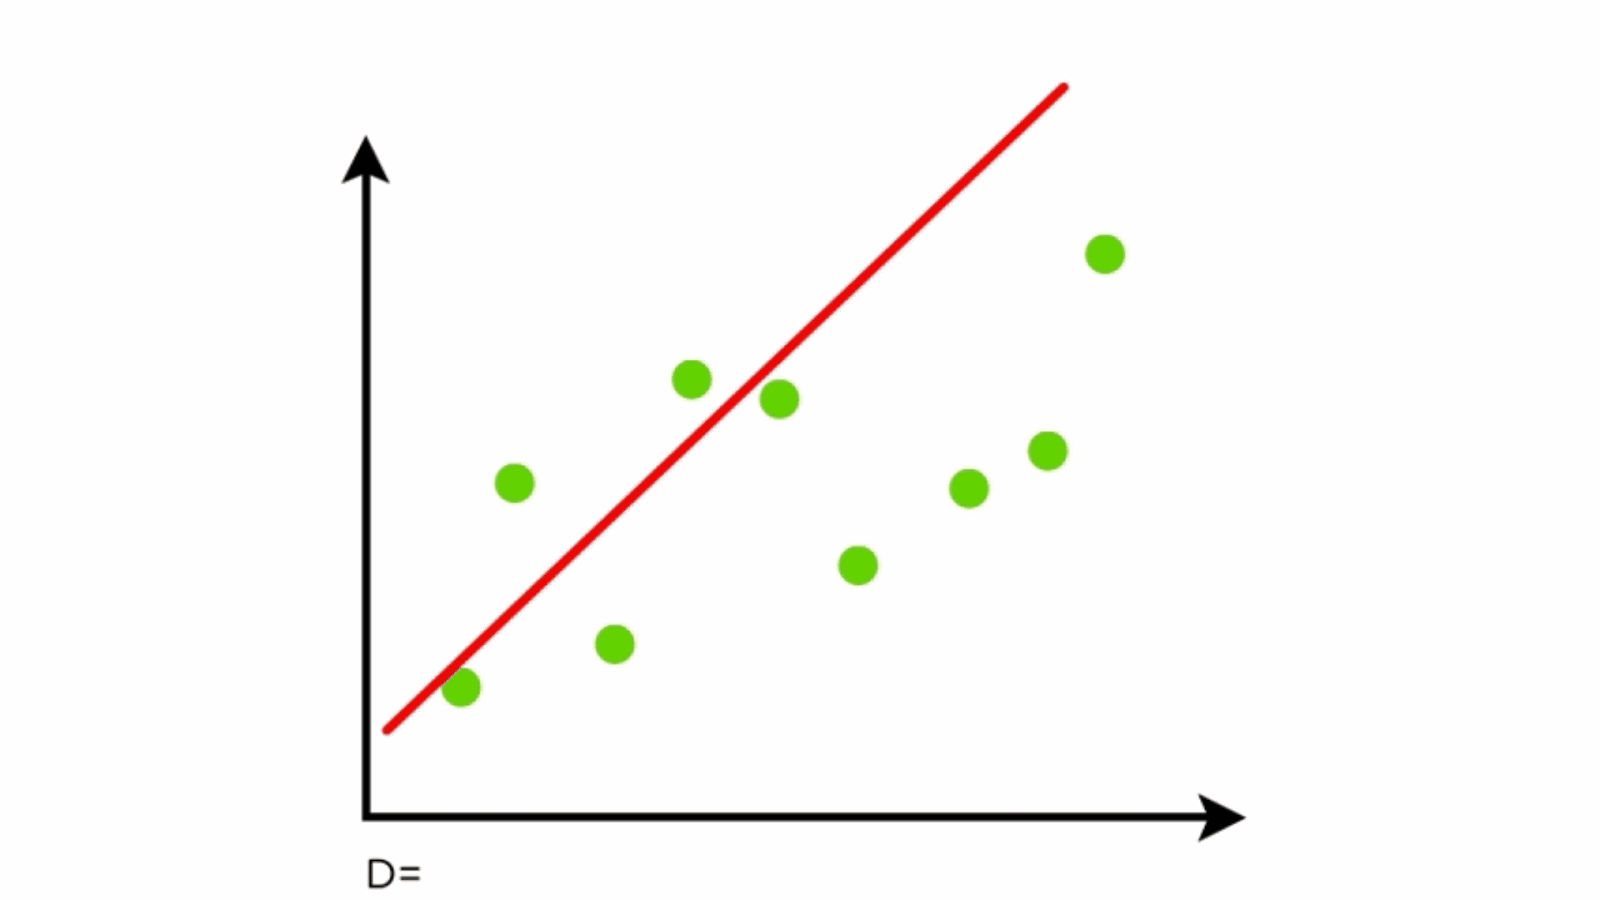

Fig 2. Least squares regression

 **Steps to do**

- Create an array of the following library of nonlinear functions on `line 172`,


$$\mathbf{\theta ( X)} =$$

$$\left\lbrack \begin{array}{cccccccccc}
| & | & | & | & | & | & | & | & | & |\\
1 & x & y & z & x^2  & y^2  & z^2  & \textrm{xy} & \textrm{yz} & \textrm{yz}\\
| & | & | & | & | & | & | & | & | & |
\end{array}\right\rbrack$$


- Click on **Run** to find the estimated governing equations using Sparse Identification.

  

Xdot = [xdot ydot zdot]; % Matrix of all the state derivatives
%Theta = ...; % Matrix of all the candidate nonlinear functions evaluated for all states

lambda = 0.1;
n = 3;


% Sparse Identification algorithm

Xi = Theta\Xdot; % Initial guess

smallinds = abs(Xi)<lambda;
Xi(smallinds) = 0;

for ind = 1:n % Regression update
    biginds = ~smallinds(:,ind);
    Xi(biginds,ind) = Theta(:,biginds)\Xdot(:,ind);
end

Xi'